clear('all');
close('all');

data_path = './output';

trials = dir(data_path);
trials = trials([trials.isdir]);
trials = {trials(3:end).name}';

NJ = cell(length(trials), 1);

for trial_idx=1:length(trials)
    trial_files = dir(fullfile(data_path, trials{trial_idx}));
    trial_files = trial_files(~[trial_files.isdir]);
    trial_files = {trial_files.name}';
    
    info = trial_files(contains(trial_files, '.txt'));
    trial_files = trial_files(contains(trial_files, '.csv'));

    info = table2array(readtable(fullfile(data_path, trials{trial_idx}, info{1}), 'ReadVariableNames', false))';
    info = cell2table(info(2, :), 'VariableNames', info(1, :));
    dt = 1 / str2double(info.samplingFrequency);
    

    data = struct('bone', [], 'position', [], 'velocity', [], 'acceleration', [], 'jerk', [], 'NJ', []);

    for file_idx=1:length(trial_files)
        bone = split(trial_files(file_idx), '_');
        bone = split(bone{end}, '.');
        bone = bone{1};
        
        data(file_idx).bone = bone;
        data(file_idx).position = table2array(readtable(fullfile(data_path, trials{trial_idx}, trial_files{file_idx})));

        data(file_idx).velocity = diff(data(file_idx).position) ./ dt;
        data(file_idx).acceleration = diff(data(file_idx).velocity) ./ dt;
        data(file_idx).jerk = diff(data(file_idx).acceleration) ./ dt;

        distance = sum(vecnorm(diff(data(file_idx).position), 2, 2));
        duration = dt * length(data(file_idx).jerk);
        data(file_idx).NJ = sqrt(0.5 * sum(vecnorm(data(file_idx).jerk, 2, 2).^2) * (duration^6) / (distance^2));
    end

    NJ{trial_idx} = [data.NJ];
end

NJ = cell2mat(NJ);
avg_NJ = mean(NJ, 1);

figure();
stradivari(NJ', 'BoxOn', 1);

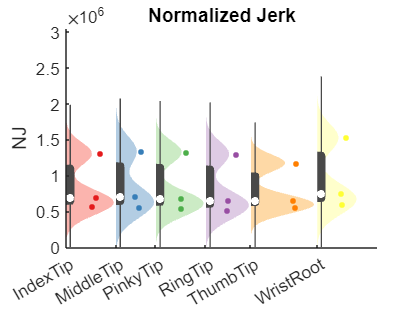

view([90, -90]);
yticklabels({data.bone})
xlim([0, max(max(NJ))*2]);
title('Normalized Jerk');
xlabel('NJ');